# Practica 1 - Métodos directos de resolución de sistemas lineales, $Ax = b$

## Problema 1

Consideremos el problema de frontera. (Hay un error en la pregunta del que no me acuerdo, el resultado no es el esperado porque no concuerdan la solucion con la EDO)

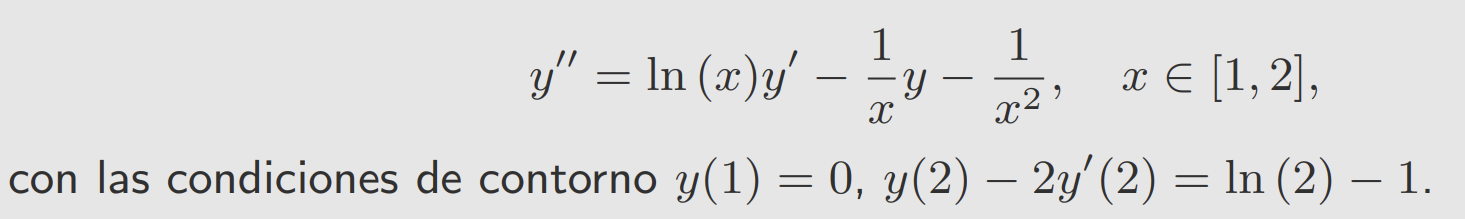

### (a) Transforma el problema en un sistema lineal de 100 ecuaciones con 100 incógnitas.

Queremos un sistema de 100 ecuaciones, donde incluimos el punto final $x=2$ como una de ellas. Por tanto, nuestro valor de h para utilizar las diferencias finitas será $h = \frac{2 - 1}{100}=0.01$. Además, para reducir la notación, $y(x_k + h) := y_{k + 1}$, $y(x_k):=y_k$ y $y(x_k - h) = y_{k - 1}$. En particular, $y(1) = 0 = y_0$. Desarrollando por diferencias finitas obtenemos:


$$\left( \frac{1}{h^2} + \frac{ln(x_k)}{2 h} \right) y_{k - 1} + \left( \frac{1}{x_k^2} - \frac{2}{h^2} \right) y_k + \left( \frac{1}{h^2} - \frac{ln(x_k)}{2 h} \right) y_{k + 1} = - \frac{1}{x_k^2}$$


Luego, para


$$\underline{k = 1}:$$


        
$$\left( \frac{1}{h^2} + \frac{ln(x_1)}{2 h} \right) y_0 + \left( \frac{1}{x_1^2} - \frac{2}{h^2} \right) y_1 + \left( \frac{1}{h^2} - \frac{ln(x_1)}{2 h} \right) y_2 = - \frac{1}{x_1^2}$$



$$\underline{k = 2}:$$


        
$$\left( \frac{1}{h^2} + \frac{ln(x_2)}{2 h} \right) y_1 + \left( \frac{1}{x_2^2} - \frac{2}{h^2} \right) y_2 + \left( \frac{1}{h^2} - \frac{ln(x_2)}{2 h} \right) y_3 = - \frac{1}{x_2^2}$$



$$\vdots$$



$$\underline{k = 100}:$$


        
$$\left( \frac{1}{h^2} + \frac{ln(x_{100})}{2 h} \right) y_{99} + \left( \frac{1}{x_{100}^2} - \frac{2}{h^2} \right) y_{100} + \left( \frac{1}{h^2} - \frac{ln(x_{100})}{2 h} \right) y_{101} = - \frac{1}{x_{100}^2}$$


Sin embargo, $y_{101}$ no deberia estar en nuestro sistema. Para eliminarlo, sustituiremos usando la condición inicial.

Sea $\beta = ln(2) - 1$.


$$y(2) - 2y'(2) = \beta \Rightarrow y_{100} - 2 \left( \frac{y_{101} - y_{99}}{2 h} \right) = \beta$$



$$\Rightarrow y_{101} = h \left( y_{100} - \beta \right) + y_{99}$$


Sustituimos y simplificamos y obtenemos para $k = 100$

        
$$\frac{2}{h^2} y_{99} + \left( \frac{1}{x_{100}} - \frac{2}{h^2} + h \right) y_{100} = \frac{\beta}{h} - \frac{\beta ln(x_{100})}{2} - \frac{1}{x_{100}^2}$$


En forma matricial queda de la siguiente manera


$$\pmatrix{ \left(\frac{1}{x_1} - \frac{2}{h^2} \right) & \left( \frac{1}{h^2} - \frac{ln(x_1)}{2 h} \right) & 0 & \cdots & \cdots & \cdots \cr \left( \frac{1}{h^2} + \frac{ln(x_2)}{2 h} \right) & \left(\frac{1}{x_2} - \frac{2}{h^2} \right) & \left( \frac{1}{h^2} - \frac{ln(x_2)}{2 h} \right) & \cdots & \cdots & \cdots \cr 0 & \ddots & \ddots & \ddots & 0 & 0 \cr 0 &0 & \ddots & \ddots & \ddots & 0 \cr \cdots & \cdots & \cdots & \left(\frac{1}{x_{99}} - \frac{2}{h^2} \right) & \left(\frac{1}{x_{99}} - \frac{2}{h^2} \right) & \left( \frac{1}{h^2} - \frac{ln(x_{99})}{2 h} \right) \cr \cdots & \cdots & \cdots & 0 & \frac{2}{h^2} & \left( \frac{1}{x_{100}} - \frac{2}{h^2} + h \right) } x = \pmatrix{ -\frac{1}{x_1^2} \cr  -\frac{1}{x_2^2} \cr \vdots \cr \vdots \cr  -\frac{1}{x_{99}^2} \cr \frac{\beta}{h} - \frac{\beta ln(x_{100})}{2}  -\frac{1}{x_{100}^2} }$$


### (b) Resuelve el sistema anterior utilizando el algoritmo de Crout. Proporciona la solución aproximada del problema en los puntos x = 1,1, x = 1,2, . . ., x = 1,9, x = 2.

Introducimos el sistema en matlab por partes, aprovechando su forma tridiagonal, utilizaremos el algoritmo de Crout.

h = (2 - 1) / 100; xk = 1:h:2; xk = xk(2:end); xk = xk(:); beta = log(2) - 1;
diagP = (1 ./ xk) - (2 / h^2);
diagP(100) = diagP(100) + h;
diagS = (1 / h^2) - (log(xk(1:end - 1)) ./ 2 * h);
diagI = (1 / h^2) + (log(xk(2:end)) ./ 2 * h);
diagI(99) = 2 / h^2;
b = -1 ./ (xk .^2);
b(100) = b(100) + (beta / h) - (beta * log (xk(100))) / 2;

Utilizamos la funcion ResolucionDirectaCrout() y obtenemos la solucion.

yk = ResolucionDirectaCrout(diagP, diagI, diagS, b);

Para obtener la solución en los puntos que se piden simplemente sabiendo que $h = 0.01$ cogemos cada 10 puntos

xk(10:10:end)'

ans =     1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


yk(10:10:end)'

ans =     0.0781    0.1472    0.2081    0.2615    0.3080    0.3479    0.3817    0.4098    0.4326    0.4503


### (c) Sabiendo que la solución exacta es y = ln (x), calcula el error máximo cometido en el apartado anterior, utilizando todos los puntos del sistema.

Aplicamos la función al vector de puntos xk y lo restamos a nuestras aproximaciones, luego sacamos el maximo del valor absoluto

f = @(x) log(x);
errMax = max(abs(yk - f(xk)))

errMax = 0.2428

### (d) Representa la solución exacta y la solución aproximada en el intervalo [1, 2]. 

Y finalmente representamos la funcion $y = ln(x)$ junto con los puntos aproximados.

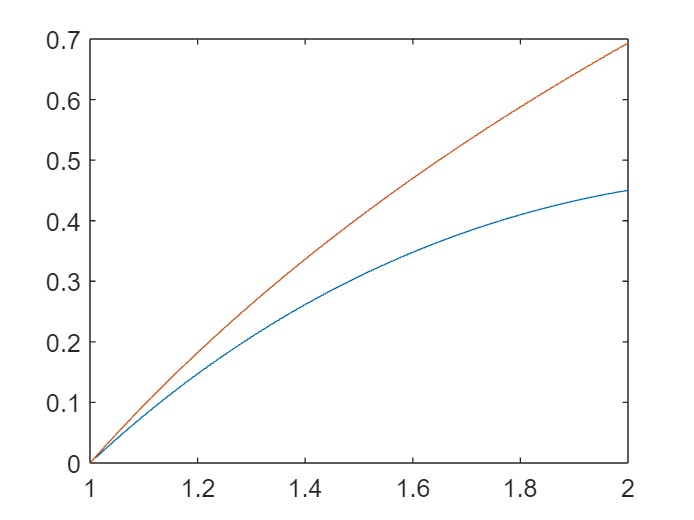

hold off

plot(xk, yk);
hold on
fplot(@(x) log(x), [1, 2]);

## Problema 2

Consideremos el sistema lineal $Ax = b$, de tamaño $n \times  n$, donde $A = (a_{ij})$ es una matriz simétrica tal que

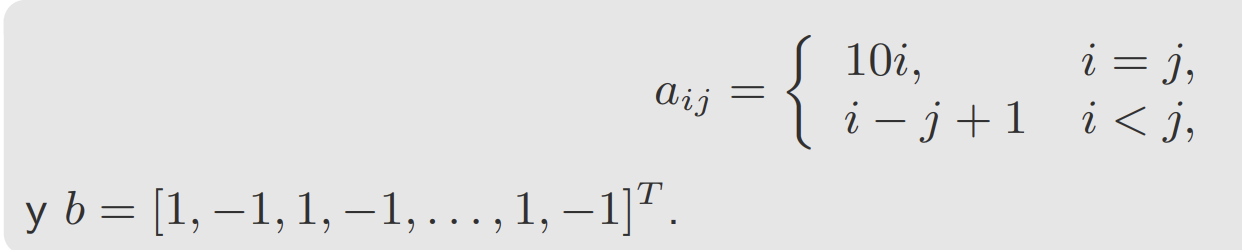

### (a) Escribe el programa que has elaborado para construir la matriz $A$ y el vector $b$. ¿Tiene el sistema $Ax = b$ solución única cuando $n = 1000$?

Creamos la función Practica1_2matriz(n) para manejar la creación de la matriz. El archivo .m está en esta misma carpeta. Luego, creamos la matriz con $n=1000$, y usando el metodo de Rouche-Frobenius, programa RF(A, b), obtenemos que es sistema compatible determinado, y por tanto, tiene solución única.

[A, b] = Practica1_2matriz(1000);
RF(A, b)

Es sistema compatible determinado.


### (b) ¿Es la matriz A definida positiva, para $n = 10$? En caso afirmativo, utiliza la factorización de Cholesky, la sustitución directa y la sustitución inversa para resolver el sistema. Proporciona la matriz $L$. 

Ahora, hacemos una segunda llamada al programa de la pregunta, con $n=10$. Luego, usamos la función DefinidaPositiva(A) para comprobar que la matriz es definida positiva.

[A, b] = Practica1_2matriz(10);
DefinidaPositiva(A);

DEFINIDA POSITIVA.


Luego, como lo és, utilizaremos la factorización de Cholesky para resolver el sistema, usando ademas la sustictucion directa e inversa.

L = FactorizacionCholesky(A)

L =     3.1623         0         0         0         0         0         0         0         0         0
         0    4.4721         0         0         0         0         0         0         0         0
   -0.3162         0    5.4681         0         0         0         0         0         0         0
   -0.6325   -0.2236   -0.0366    6.2888         0         0         0         0         0         0
   -0.9487   -0.4472   -0.2377   -0.1127    6.9879         0         0         0         0         0
   -1.2649   -0.6708   -0.4389   -0.3126   -0.2346    7.5898         0         0         0         0
   -1.5811   -0.8944   -0.6401   -0.5126   -0.4450   -0.4145    8.1029         0         0         0
   -1.8974   -1.1180   -0.8412   -0.7125   -0.6555   -0.6450   -0.6742    8.5226         0         0
   -2.2136   -1.3416   -1.0424   -0.9124   -0.8659   -0.8756   -0.9359   -1.0549    8.8247         0
   -2.5298   -1.5652   -1.2436   -1.1124   -1.0763   -1.1062   -1.1975   -1.3629   -1.6


% Usamos la funcion ResolucionDirectaCholesky(A, b)
% que resuelve el sistema usando esta factorizacion

sol = ResolucionDirectaCholesky(A, b)

sol =     0.1334
   -0.0380
    0.0441
   -0.0161
    0.0291
   -0.0077
    0.0238
   -0.0026
    0.0218
    0.0012


Comprobamos que sea solucion viendo que la diferencia $A \cdot sol - b$ es muy cercana a 0

dif = A * sol - b

dif = 1.0e-15 *

    0.2220
    0.1110
    0.2220
         0
   -0.2220
         0
    0.2220
   -0.2220
         0
   -0.2220


### (c) ¿Sigue siendo la matriz definida positiva para $n = 500$? Si no lo es, utiliza la factorización de Crout para resolver el sistema. Proporciona las matrices $L$ y $D$.

Usamos la funcion del problema para obtener la A con $n=500$, y luego, comprobamos si es definida positiva.

[A, b] = Practica1_2matriz(500);
DefinidaPositiva(A);

NO DEFINIDA POSITIVA.


Vemos que no es definida positiva, por lo que usaremos la factorizacion de Crout.

[L, D] = FactorizacionCrout(A)

L =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

D = 1.0e+03 *

    0.0100
    0.0200
    0.0299
    0.0395
    0.0488
    0.0576
    0.0657
    0.0726
    0.0779
    0.0800



% Usamos la funcion ResolucionDirectaFactCrout(A, b)
% que resuelve el sistema usando esta factorizacion

sol = ResolucionDirectaFactCrout(A, b)

sol =     0.0697
   -0.0649
    0.0268
   -0.0297
    0.0173
   -0.0189
    0.0128
   -0.0138
    0.0103
   -0.0108


Comprobamos que sea solucion viendo que la diferencia $A \cdot sol - b$ es muy cercana a 0

dif = A * sol - b

dif = 1.0e-10 *

    0.0000
    0.0000
   -0.0000
   -0.0001
    0.0000
    0.0001
    0.0001
    0.0001
   -0.0001
    0.0000


## Problema 3

Consideremos la matriz de tamaño 4 × 3

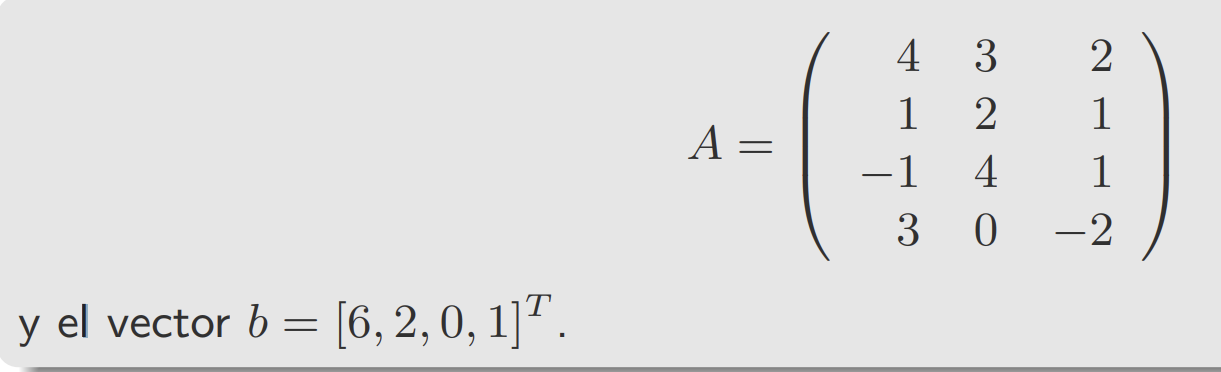

### (a) Escribe cómo se construyen las matrices de Householder H1, H2 y H3 que transforman la matriz A en una matriz escalonada A4. Construye a partir de ellas la factorización QR de A. Proporciona Q y R.

Para construir las matrices H seguimos el siguiente procedimiento. Tomamos la primera columna de A a partir del primer elemento (toda la columna), aplicamos la formula de la matriz de Householder de ese vector: $H(v) = I_n - \frac{2}{||v||_2^2} \left( v v^* \right)$. Luego, extendemos la matriz de Householder para que sea cuadrada y de tamaño igual al de las filas de A. Premultiplicamos A por la matriz de Householder y obtenemos A'. Repetimos con la segunda columna cogiendo a partir del segundo elemento, y asi sucesivamente hasta que hemos anulado toda la parte inferior de A. Obtenemos una escalonada R tal que $R = H_n \ldots H_2 H_1 A$. Luego, al ser las matrices H ortogonales, su producto tambien lo es y su inversa es su traspuesta. La llamaremos Q, luego $Q R = A$. Obtendremos la factorizacion a partir del programa TriangulizacionHouseholder()

A = [4, 3, 2; 1, 2, 1; -1, 4, 1; 3, 0, -2]; b = [6; 2; 0; 1];
[Q, R] = TriangulizacionHouseholder(A)

Q =    -0.7698   -0.3019   -0.4672    0.3131
   -0.1925   -0.3240   -0.0912   -0.9218
    0.1925   -0.8689    0.3960    0.2261
   -0.5774    0.2209    0.7853   -0.0348


R =    -5.1962   -1.9245   -0.3849
    0.0000   -5.0295   -2.2386
    0.0000   -0.0000   -2.2001
    0.0000    0.0000   -0.0000


### (b) Determina cuántas soluciones tiene el sistema Ax = b.

Para determinar esto usaremos Rouche-Frobenius

RF(A, b)

Es sistema compatible determinado.


Es sistema compatible determinado y por tanto tiene una sola solución.

### (c) Resuelve el sistema utilizando la factorización QR anterior

Tenemos que $Q R = A$ y $A x = b$, luego $Q R x = b$. Sea $z = Q^{-1} b = Q^* b$, entonces podremos resolver $R x = z$ facilmente por sustitucion inversa.

z = Q' * b

z =    -5.5811
   -2.2386
   -2.2001
   -0.0000


x = SustitucionInversa(R, z)

x =     1.0000
   -0.0000
    1.0000


Obtenemos la solución x. Comprobamos que es solución.

A * x - b

ans = 1.0e-15 *

         0
   -0.2220
   -0.4441
         0


Vemos que la diferencia es muy pequeña y por tanto, debe ser solución.